# Task 1: Image Processing

## Task description

Three provided images should be processed and anaylsed. The processed images should be saved accordingly. The provided images are RGB.png files. The pictures should be turned into 

(1) a greyscale picture

(2) into a binary picture

The binary picture should be saved separetly as a *.png file. With the binary picture, the area, the perimeter and the convex hull should be calculated and displayed in a plot.  

## Converting and writing the pictures

In this step, the imported picture should be turned into a greyscale picture and a binary picture.

%[file, path] = uigetfile('.png'); % retrieving my picture from folder
%addpath(path);

%[RGB, GREY, BIN] = read_img(file);
%write_img(GREY, path);
%write_img(BIN, path);


### Explanation

(Ex_old) First the picture file gets loaded including the path. The picture is then displayed to see how the original picture looked like. The RGB picture needs to be read with the 'imread' function. This returns a 3 dimensional array with the red, green and blue values of the picture. Afterwards, the image can be converted into a greyscale picture with the 'rgb2gray' function. The greyscale picture gets displayed with the function 'imshow'.  The greyscale picture can further be converted into a binary picture with the function 'imbinarize'. This picture gets displayed as well. 

(Ex_new) The logic and code of reading and showing the picture was turned into a function.

## Calculations

In this chapter, the area, the perimeter and the convex hull are calculated and displayed in a graph/plot. 

% [area, perimeter, convex_hull] = img_stats(BIN)

### Explanation

(Ex_old) With the 'regionprops' function, different parameters can be extracted. By telling the function the parameters 'Area', 'Perimeter' and 'ConvexHull', those get calculated. In the follwing three lines, the different values get extracted and assigned to a variable. 

(Ex_new) The logic and code of reading and showing the picture was turned into a function.

## Displaying the results

% plot_convex_hull(BIN)

## for loop

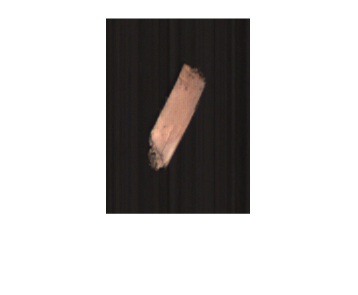

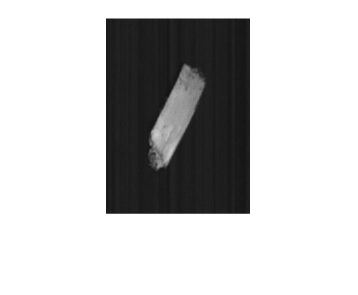

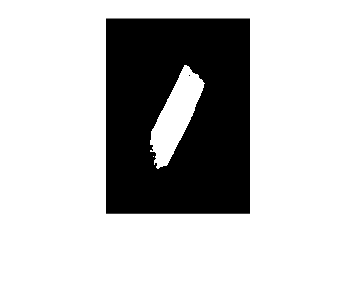

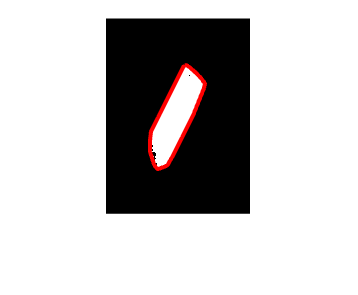

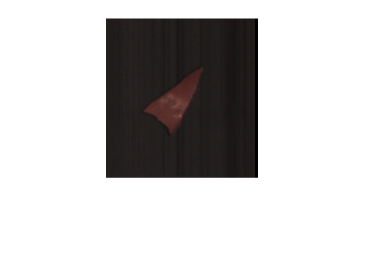

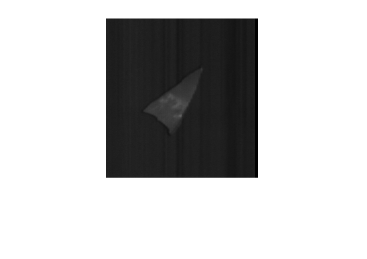

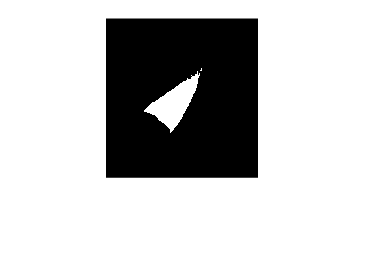

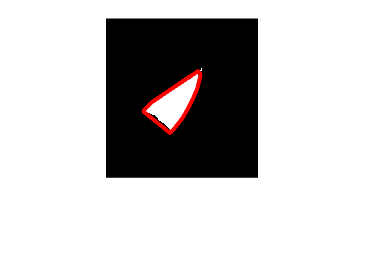

prefix = 'bsp*'; % the star is necessary to make clear that after 'bsp' there is still something coming
folders = dir(prefix); % lists contents of folders

for i = 1:length(folders)
    
    folder = folders(i).name;
    addpath(folder);

    [RGB, GREY, BIN] = read_img('RGB.png');
    
    write_img(GREY, folder);
    write_img(BIN, folder);

    plot_convex_hull(BIN); % for displaying the area and perimeter, call function 'img_stats(img)'

    rmpath(folder); % removes the current path so it works for the next loop

end

### Explanation

After the task was performed for one picuture, every step got transformed into a function to make the loop easier to understand and to keep the code as short as possible. Before the loop, a prefix 'bsp' is defined. This prefix allows me to search for all the pictures within the folders starting with bsp. The star * defines that after the prefix, there is still something coming. Without the star, the code only searches for folders that are names 'bsp'. The 'dir' function lists the contents of the folders.

The loop starts by looping through the folders that start with 'bsp'. A path was added, so the code knows, where to find the folders and the contents of each folder.

The 'read_img' function was created to make converting the images into greyscale and binary easier. Afterwards, each image gets saved within the repective folder with the created function 'write_img'. For the plotting of the convex hull, a function was created as well. At the end of the loop, the path needs to be removed again, so a new path can be created for the next folder.

Note that this code only works with folders called 'bsp' and images called 'RBG.png'. If the names differ but still follow a logic like in this exercise, the names in the code can be adapted however needed.

## Functions

function [RGB, GREY, BIN] = read_img(file)
    
    RGB = imread(file);
    GREY = rgb2gray(RGB);
    BIN = imbinarize(GREY);

    imshow(RGB);
    figure;
    imshow(GREY);
    figure;
    imshow(BIN);
    figure;
end


function write_img(img, path)

    file = append(inputname(1), '.png'); % takes the name of the input image.

    output = fullfile(path, file); % creates path and name.
    imwrite(img, output);
end


function [area, perimeter, convex_hull] = img_stats(img)

    stats = regionprops(img, 'Area');

    % area index is needed to clarify which area the biggest one is
    [area, area_index] = max([stats.Area]);

    % bwlabel gives information about all the areas in the image and 
    % connects it with each other. If the img has 3 areas then 
    % the first area is defined by 1s the second by 2s etc.
    labeled_img = bwlabel(img); 

    % the labeled image and area index get compared. The area index returns
    % the area that i want while the labeled img actually gives information
    % about the 'looks' of the area.
    filtered_img = labeled_img == area_index;
    stats = regionprops(filtered_img, 'Perimeter',  'ConvexHull');
    perimeter = stats.Perimeter;
    convex_hull = stats.ConvexHull;

end


function plot_convex_hull(img)

    [~, ~, convex_hull] = img_stats(img);
    imshow(img)
    hold on
    plot(convex_hull(:,1), convex_hull(:,2), 'r', 'LineWidth', 2)
    hold off
    figure;
end


### Explanation

#### read_img(file)

This function was created to simplify the conversion of each image. The selected RGB image is converted into a greyscale image which gets converted in a binary image. Each image gets displayed. 

#### write_img(img, path)

This function automazes writing of image files. The name of the input image is taken and '.png' is added in order to create the full name of the file. The function uses the path that is give and the name of the image to create a new file within the folder that is looked at. 

#### img_stats(img)

This function was the most difficult one. The input needs to be a binary picture because the function 'regionprops' only reads 1 and 0. First the area is calculated with the function 'regionprops'. If more than one area is noteable in the picture, only the biggest area is of interest. Therefore, the max area and the area index are asigned to variabels. 

The 'bwlabel' function is needed to label all the connected areas accordingly. In this exercise, bsp38 has more than one area in the image. The max area returns the value of the biggest area and the index returns the position of the max area within the array of area. For bsp38, the biggest area has the index 6. The labeled_img has multiple areas that are indexed as well. The first area is indexed with 1s, the second area with 2s and so on. The biggest area is indexed with 6s. By comparing the labeled_img with the area_index, all values that are not a 6 get turned into a 0 and all 6 are converted into a 1 so another binary picture gets created with the biggest area. This is called the filtered_img. The perimeter and the convex hull are calculated with the function 'regionprops'.

#### plot_convex_hull(img)

This function was created to display the convex hull ontop of the binary picture. It also only functions with binary pictures as an input as it calles the 'img_stats' function. The 'img_stats' gets called to retrieve the convex hull of the image. First the image gets displayed and ontop of the displayed image, the convex hull gets plotted. The colour is set to red and the line width was set to 2. 